Dlaczego licznik i mianownik w kryterium Nyquista muszą być względnie pierwsze?

Rozważmy dwie transmitancje:


$$G_s(s) = \frac{1}{s + 1}, G_f(s)=\frac{2+s}{(1+s)(2+s)}$$


num_s = 1;
den_s = [1, 1];

eps = 1e-3;
num_f = [1 -eps];
den_f = [1, 1-eps, -eps];

% Transmitancje
tf_f = tf(num_f, den_f);
tf_s = tf(num_s, den_s);

% State-space
[A_f, B_f, C_f, D_f] = tf2ss(num_f, den_f);
[A_s, B_s, C_s, D_s] = tf2ss(num_s, den_s);
ss_f = ss(A_f, B_f, C_f, D_f);
ss_s = ss(A_s, B_s, C_s, D_s);

Charakterystyki Nyquista dla każdego z tych obiektów wyglądają identycznie:

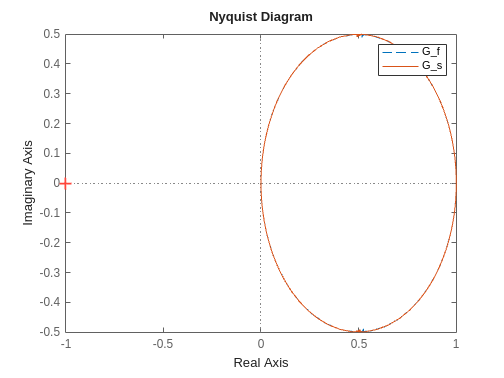

figure;
hold on;
grid on;
nyquist(ss_f, "--");
nyquist(ss_s, "-");
legend("G_f", "G_s");

Odpowiedzi skokowe:

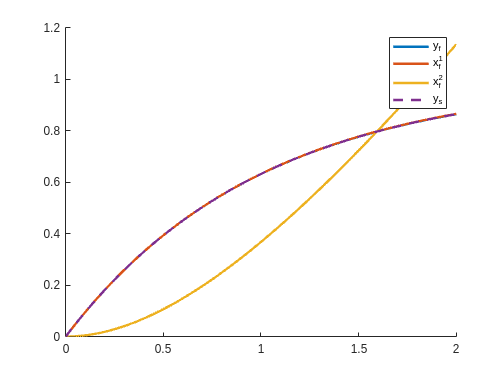

t = 0:0.01:2;
[~, y_f] = ode45(@(t, x)A_f*x + B_f, t, [0;0]);
[~, y_s] = ode45(@(t, x)A_s*x + 1, t, 0);

figure()
hold on;
legend("show");
plot(t, C_f(1)*y_f(:, 1) + C_f(2)*y_f(:, 2), "DisplayName", "y_{f}", "LineWidth", 2);
plot(t, y_f(:, 1), "DisplayName", "x_{f}^{1}", "LineWidth", 2);
plot(t, y_f(:, 2), "DisplayName", "x_{f}^{2}", "LineWidth", 2);
plot(t, y_s(:, 1), "--", "DisplayName", "y_{s}", "LineWidth", 2);

Widać zatem, że istotna jest dynamika, która "siedzi" w mianowniku, mimo redukcji z licznikiem. Wyjście jest identyczne, lecz wewnątrz mogą istnieć stany niestabilne, które w praktyce mogą zniszczyć obiekt.